# Scenario comparison (Improved version)

This is an improved version of the Scenario Comparison. We have included a comparison that plots similar curves to those shown in John Hopkin's COVID-19 Dashboard. 

What they show in their data is:

- Weekly cases (which would be our simulated infection curves using a moving average of 7 days of data).

- Weekly death: Daily deaths curve averaged on 7 days.

- Weekly doses administered (this one i will omit, except in the case of vaccination and the complete policies scenario)

## Real data (Mexico) - New infection and death cases

mexicoDataReader = CoronaMexicoReader();
[mexicoNewCases, mexicoDeaths, mexicoRecovered, info] = mexicoDataReader.readMexicoDataTable();
disp(info);

New cases data gathered from 1/22/20 to 11/14/22
Death cases data gathered from 1/22/20 to 11/15/22
Recovered cases data gathered from 1/22/20 to 11/15/22



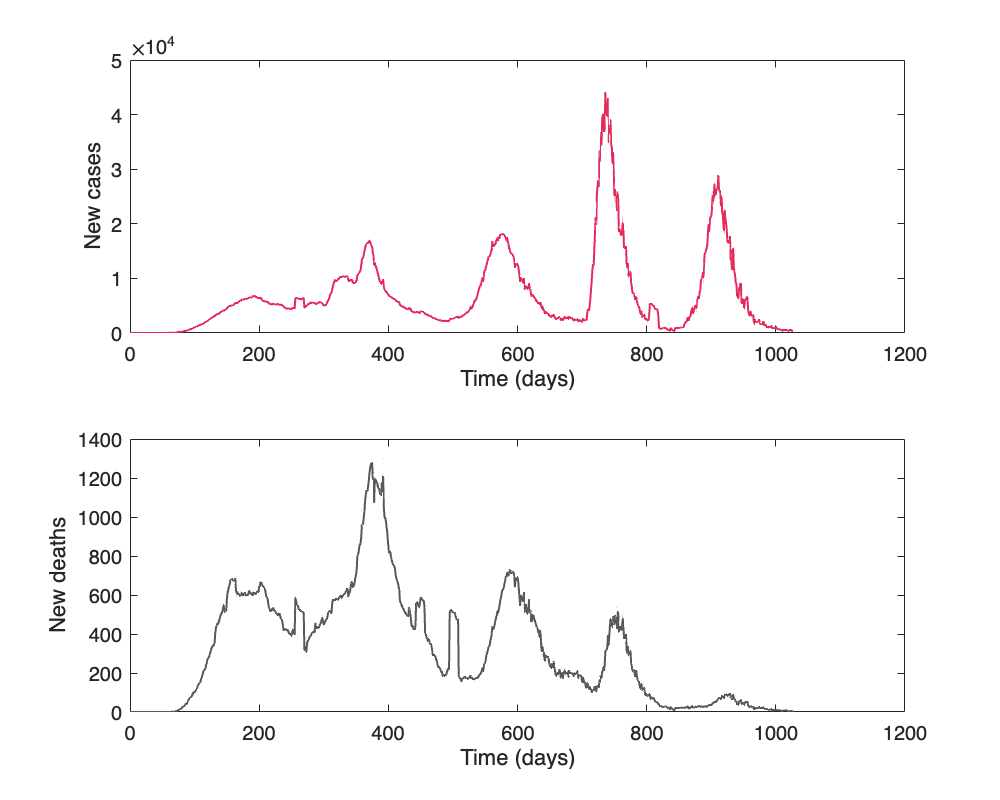

addpath('src')

days = 1:length(mexicoNewCases);
infectionColor = "#e32b5c";
deathColor = "#595959";
recoveredColor = "#4de645";

%Aplicamos media movil de 7 dias
filterCoeffs = ones(1,14)*(1/14);
filterer = Filterer();
mexicoNewCases = filterer.applyFIRFilter(mexicoNewCases,filterCoeffs);
mexicoDeaths = filterer.applyFIRFilter(mexicoDeaths, filterCoeffs);
mexicoRecovered = filterer.applyFIRFilter(mexicoRecovered, filterCoeffs);


f = figure();
f.Position = [0 0 500 400];
%sgtitle("Real data Mexico")
subplot(2,1,1)
plot(1:length(mexicoNewCases), mexicoNewCases,'Color', infectionColor, 'LineWidth', 1)
xlabel("Time (days)")
ylabel("New cases")
subplot(2,1,2)
plot(1:length(mexicoDeaths), mexicoDeaths, 'Color', deathColor, 'LineWidth',1)
xlabel("Time (days)")
ylabel("New deaths")

%matlab2tikz()

## Real data (Mexico) - Mobility data

Taken in a period that lasted from 15 February 2020 to 15 September 2022

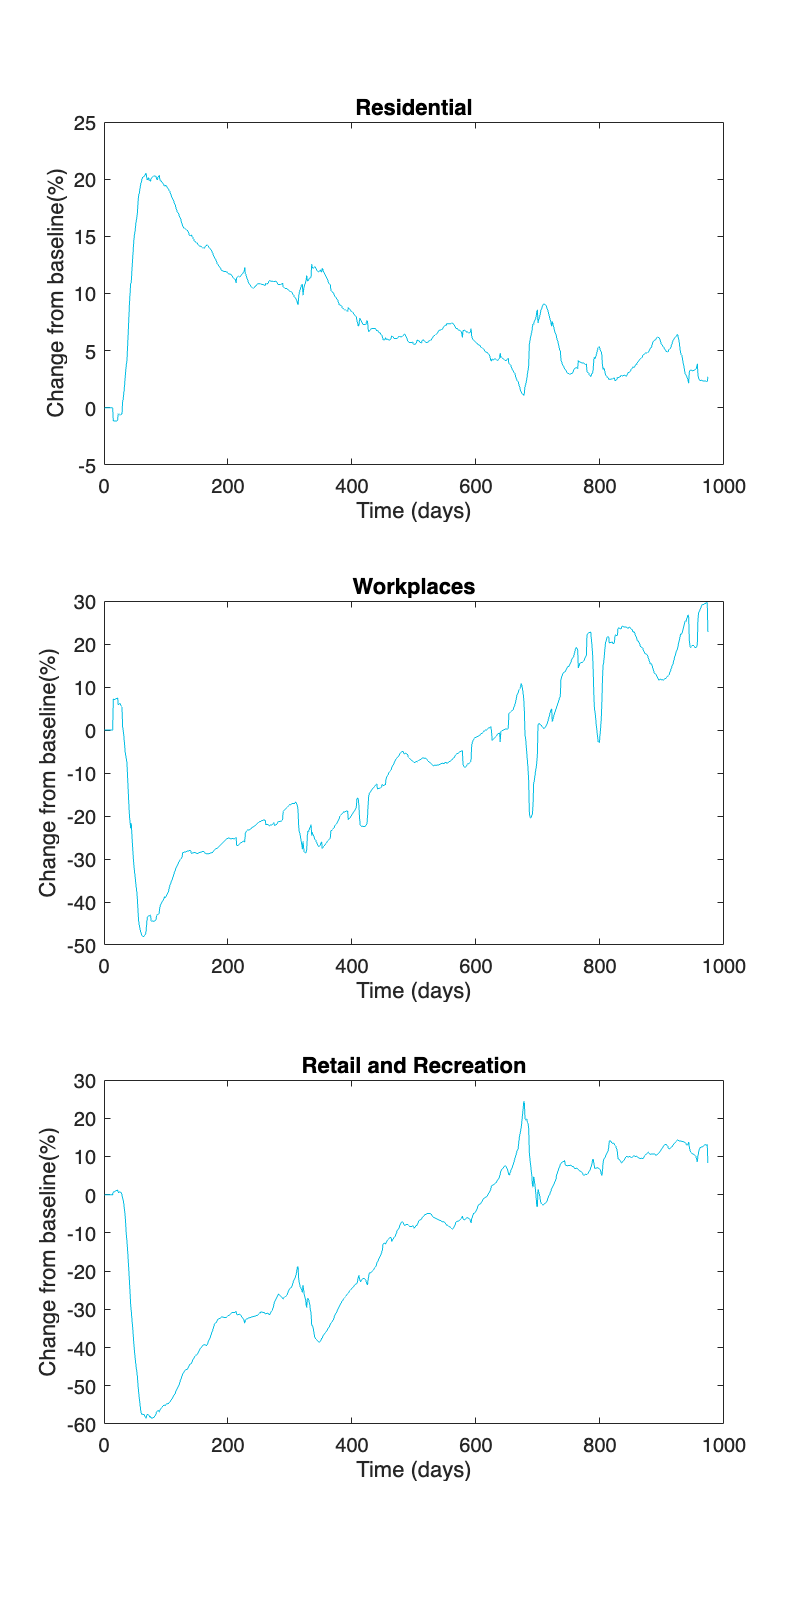

rowCuts = [2, 322; 2,366; 2,289];
dataPaths = ["2020_MX_Region_Mobility_Report.csv", "2021_MX_Region_Mobility_Report.csv", "2022_MX_Region_Mobility_Report.csv"];
columnCuts = [10,11,12,13,14,15];

[placesNames, placeData] = mexicoDataReader.readFullMobilityData(dataPaths, rowCuts, columnCuts);
%I don't like the names used in the raw data, so let's make them more
%presentable 
placesNames = ["Retail and Recreation", "Grocery and Pharmacy", "Parks", "Transit Stations", "Workplaces", "Residential"];
f = figure();
f.Position = [0 0 400 800];
indexesToPlot = [6,5,1];
for i = 1:length(indexesToPlot)
    hold on 
    subplot(length(indexesToPlot), 1, i)
    plot(placeData(:,indexesToPlot(i)), 'Color', '#00bde3')
    title({'';placesNames(indexesToPlot(i))})
    ylabel("Change from baseline(%)")
    xlabel("Time (days)")
    hold off
end

%matlab2tikz()

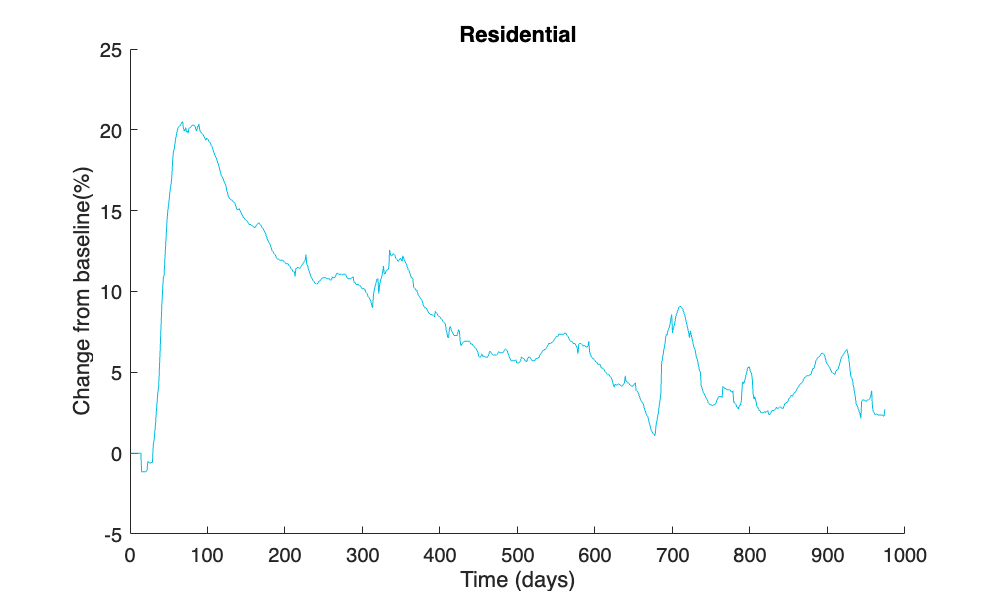

f = figure();
f.Position = [0 0 500 300];
hold on 
    plot(placeData(:,indexesToPlot(1)), 'Color', '#00bde3')
    title({'';placesNames(indexesToPlot(1))})
    ylabel("Change from baseline(%)")
    xlabel("Time (days)")
hold off

%matlab2tikz();

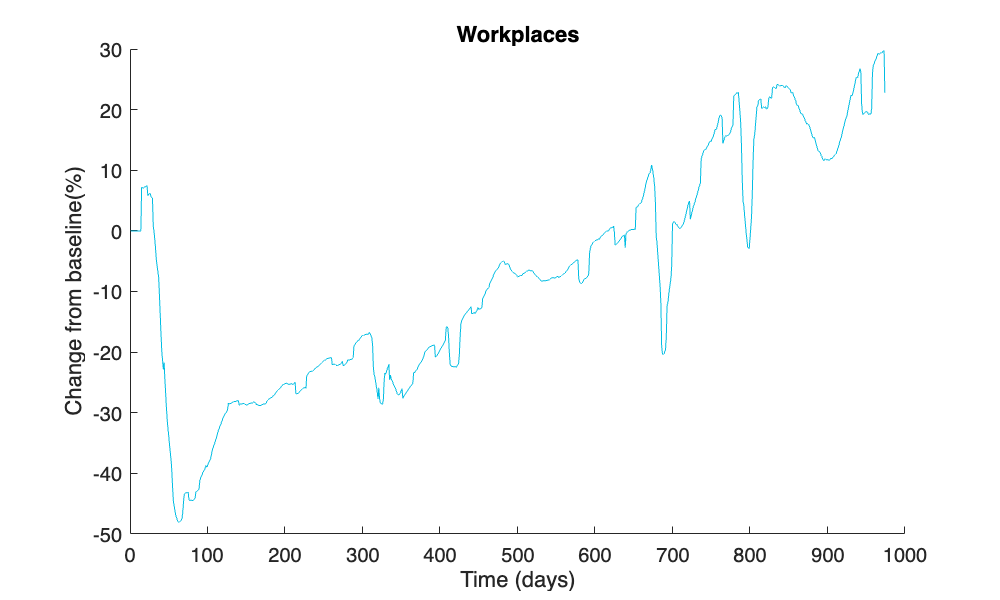

f = figure();
f.Position = [0 0 500 300];
hold on 
    plot(placeData(:,indexesToPlot(2)), 'Color', '#00bde3')
    title({'';placesNames(indexesToPlot(2))})
    ylabel("Change from baseline(%)")
    xlabel("Time (days)")
hold off

%matlab2tikz();

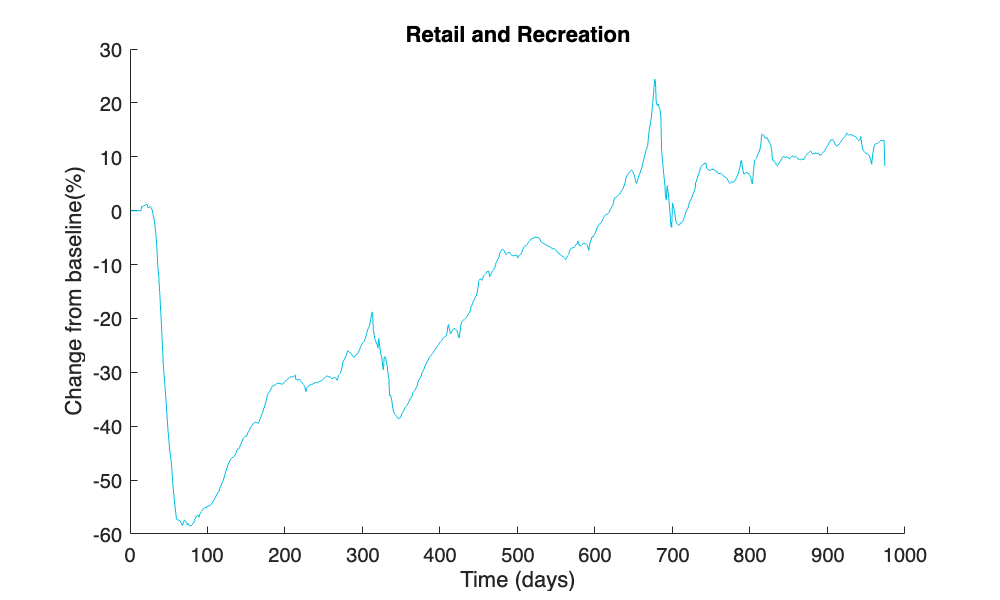

f = figure();
f.Position = [0 0 500 300];
hold on 
    plot(placeData(:,indexesToPlot(3)), 'Color', '#00bde3')
    title({'';placesNames(indexesToPlot(3))})
    ylabel("Change from baseline(%)")
    xlabel("Time (days)")
hold off

%matlab2tikz();

## Individual scenarios new cases and deaths

FsSEIRD = 1;
FsPlaces = 2*(24);
neutralScenario = ScenarioData('Neutral_data/exp_1/grafica.csv', 'Neutral_data/exp_1/city_info.csv', FsSEIRD, FsPlaces);
isolationScenario = ScenarioData('Isolation_data/exp_1/grafica.csv', 'Isolation_data/exp_1/city_info.csv', FsSEIRD, FsPlaces);
maskScenario = ScenarioData('Mask_usage_data/exp_1/grafica.csv', 'Mask_usage_data/exp_1/city_info.csv', FsSEIRD, FsPlaces);
socialDistancingScenario = ScenarioData('Social_distancing_data/exp_1/grafica.csv', 'Social_distancing_data/exp_1/city_info.csv', FsSEIRD, FsPlaces);
vaccinationScenario = ScenarioData('vaccination_data/grafica.csv', 'vaccination_data/city_info.csv', FsSEIRD, FsPlaces);

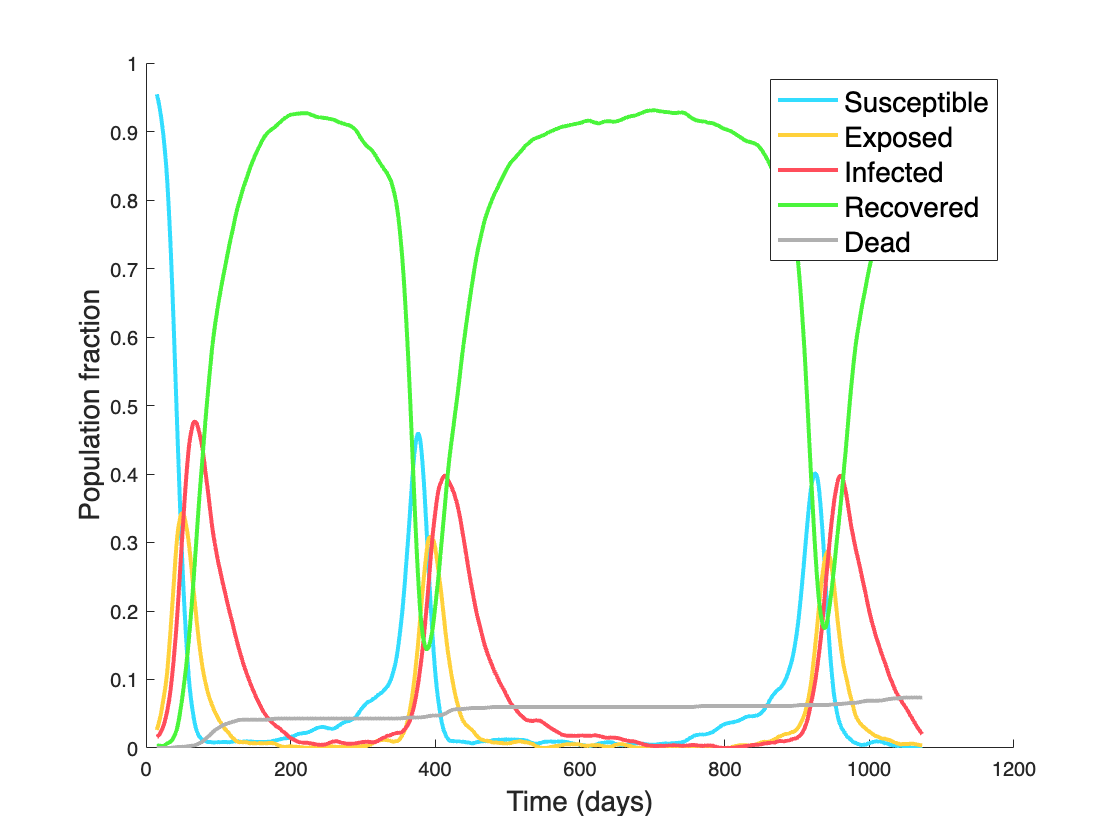

%Escenario sin política SEIRD
dataNeutral = importdata("Neutral_data/exp_1/grafica.csv").data;
nPopulation = sum(dataNeutral(1,:));
Fs = 1;
tArray = (1:size(dataNeutral,1))*(1/Fs);
series = {dataNeutral(:,1), dataNeutral(:,3), dataNeutral(:,4), dataNeutral(:,1), dataNeutral(:,2)};


colors = {[51/255,221/255,255/255],[255/255,209/255,59/255], [255/255,77/255,91/255], [74/255,245/255,59/255], [176/255,176/255,176/255]};
series = {neutralScenario.susceptibleSeries, neutralScenario.exposedSeries, neutralScenario.infectedSeries, neutralScenario.recoveredSeries, neutralScenario.deathSeries};
seriesNames = ["Susceptible", "Exposed", "Infected", "Recovered", "Dead"];

f = figure();

hold on 
for i = 1:length(series)
    plot(tArray(15:end), series{i}(15:end), 'Color', colors{i}, 'DisplayName', seriesNames(i), 'LineWidth', 2)
end
hold off
xlabel("Time (days)", 'FontSize',14)
ylabel("Population fraction",'FontSize',14)
legend('FontSize',14, 'Location',"northeast");

### No policy

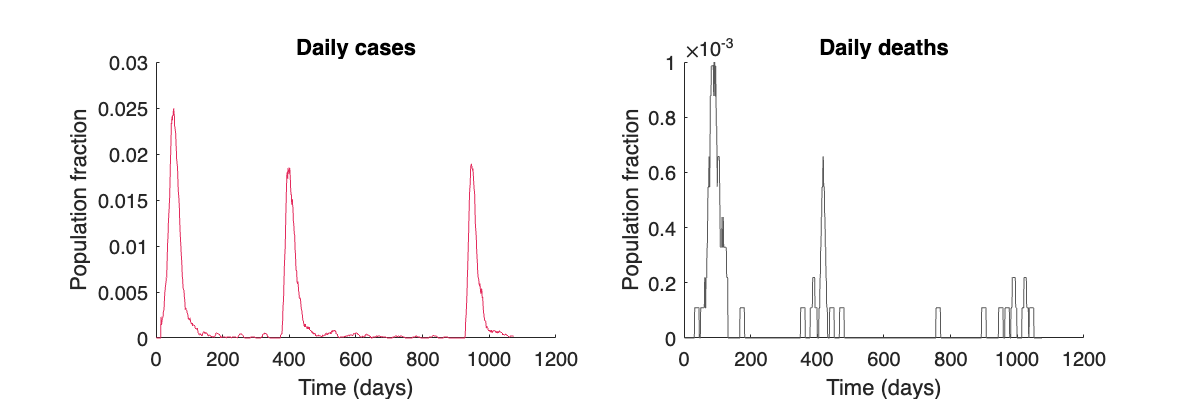

%Escenario sin política
f = figure();
f.Position = [0 0 600 200];
subplot(1,2,1)
hold on 
neutralScenario.plotNewCases();
hold off
title({'';"Daily cases"})
%ylim([0,0.03])
xlabel("Time (days)")
ylabel("Population fraction")
xlim([0,1200])
ylim([0,0.03])
subplot(1,2,2)
hold on 
neutralScenario.plotNewDeaths();
hold off
title({'';"Daily deaths"})
xlabel("Time (days)")
ylabel("Population fraction")
xlim([0,1200])
ylim([0,1*10^-3])

%matlab2tikz()

### Lockdown policy

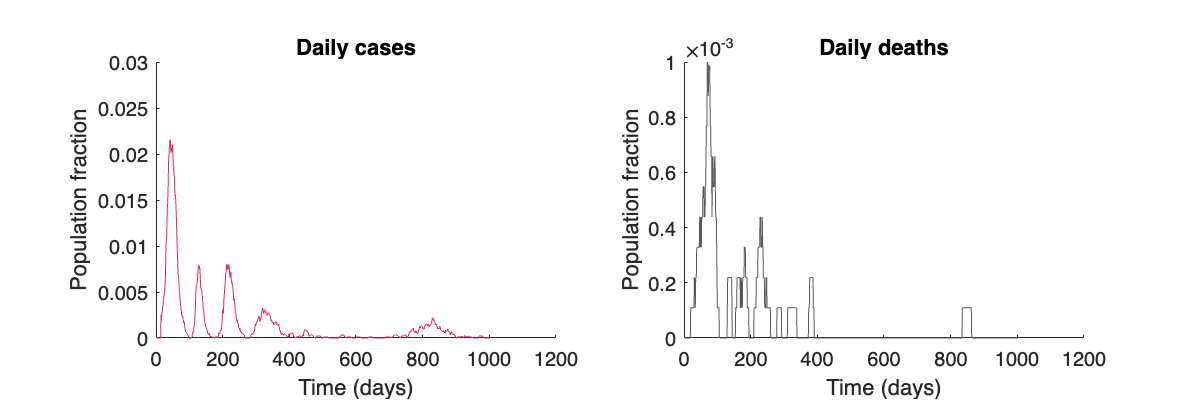

%Isolation policy
f = figure();
f.Position = [0 0 600 200];
subplot(1,2,1)
hold on 
isolationScenario.plotNewCases();
hold off
title({'';"Daily cases"})
xlabel("Time (days)")
ylabel("Population fraction")
xlim([0,1200])
ylim([0,0.03])
subplot(1,2,2)
hold on 
isolationScenario.plotNewDeaths();
hold off
title({'';"Daily deaths"})
xlabel("Time (days)")
ylabel("Population fraction")
xlim([0,1200])
ylim([0,1*10^-3])

%matlab2tikz()

### Mask use policy

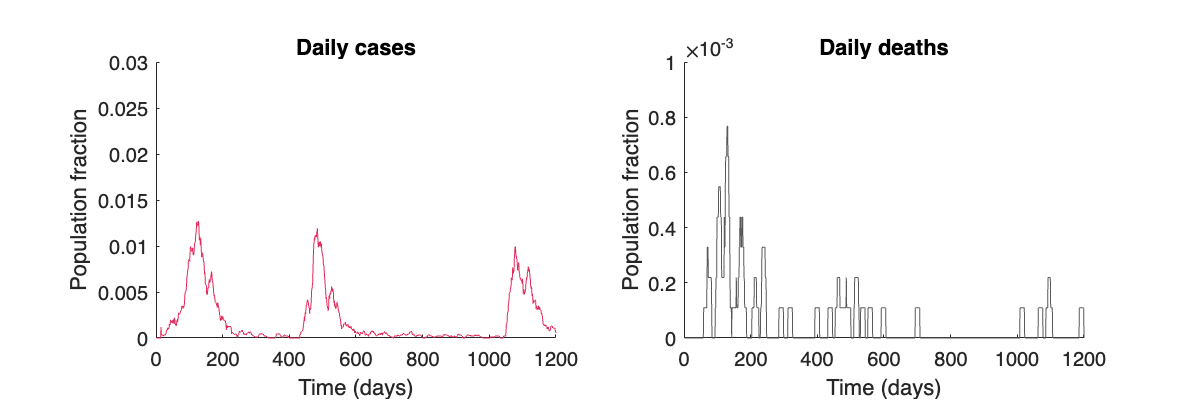

%Mask use scenario 
f = figure();
f.Position = [0 0 600 200];

subplot(1,2,1)
hold on 
maskScenario.plotNewCases();
hold off
title({'';"Daily cases"})
xlabel("Time (days)")
ylabel("Population fraction")
xlim([0,1200])
ylim([0,0.03])
subplot(1,2,2)
hold on 
maskScenario.plotNewDeaths();
hold off
title({'';"Daily deaths"})
xlabel("Time (days)")
ylabel("Population fraction")
xlim([0,1200])
ylim([0,1*10^-3])

% matlab2tikz()

### Social distancing

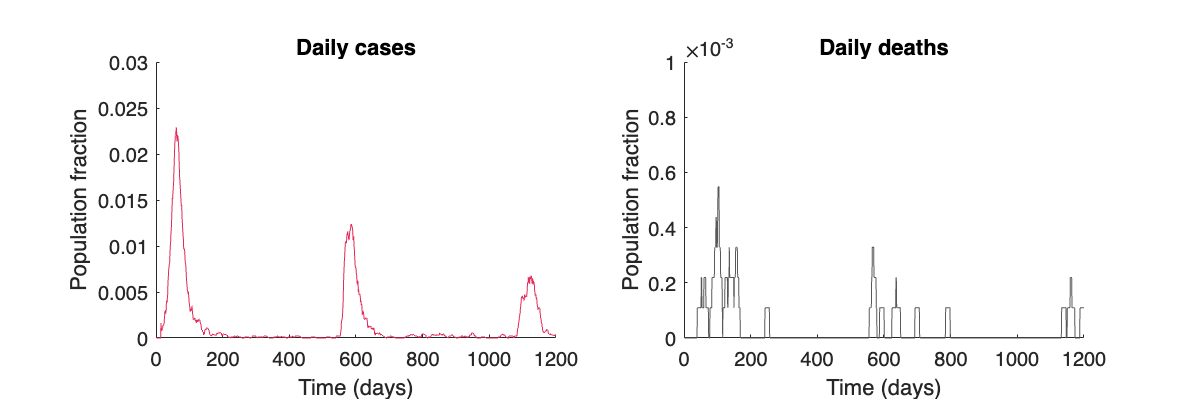

%Social distancing policy

f = figure();
f.Position = [0 0 600 200];

subplot(1,2,1)
hold on 
socialDistancingScenario.plotNewCases()
hold off
title({'';"Daily cases"})
xlabel("Time (days)")
ylabel("Population fraction")
xlim([0,1200])
ylim([0,0.03])
subplot(1,2,2)
hold on 
socialDistancingScenario.plotNewDeaths();
hold off
title({'';"Daily deaths"})
xlabel("Time (days)")
ylabel("Population fraction")
xlim([0,1200])
ylim([0,1*10^-3])

%matlab2tikz()

### Vaccination

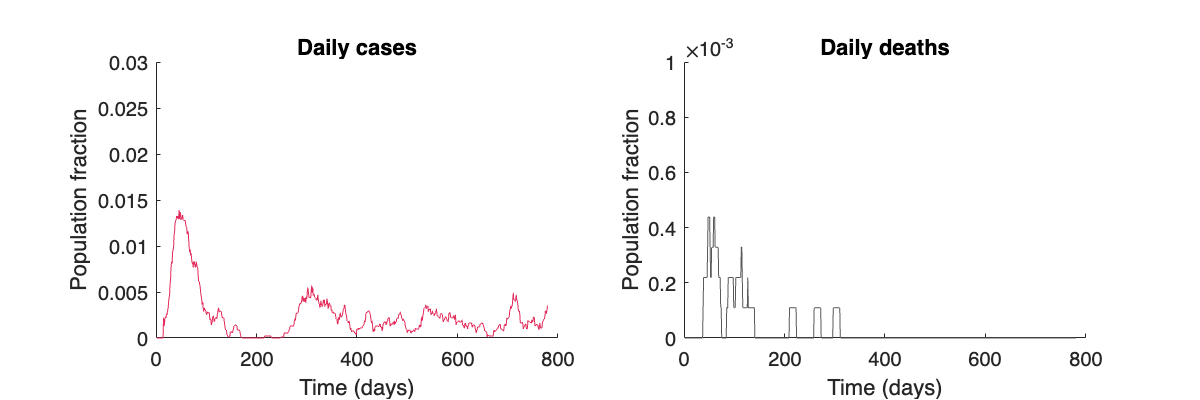

%Vaccination policy

f = figure();
f.Position = [0 0 600 200];

subplot(1,2,1)
hold on 
vaccinationScenario.plotNewCases();
hold off
title({'';"Daily cases"})
xlabel("Time (days)")
ylabel("Population fraction")
%xlim([0,800])
ylim([0,0.03])
subplot(1,2,2)
hold on 
vaccinationScenario.plotNewDeaths();
hold off
title({'';"Daily deaths"})
xlabel("Time (days)")
ylabel("Population fraction")
%xlim([0,1200])
ylim([0,1*10^-3])

%matlab2tikz()

### Multi-policy scenario

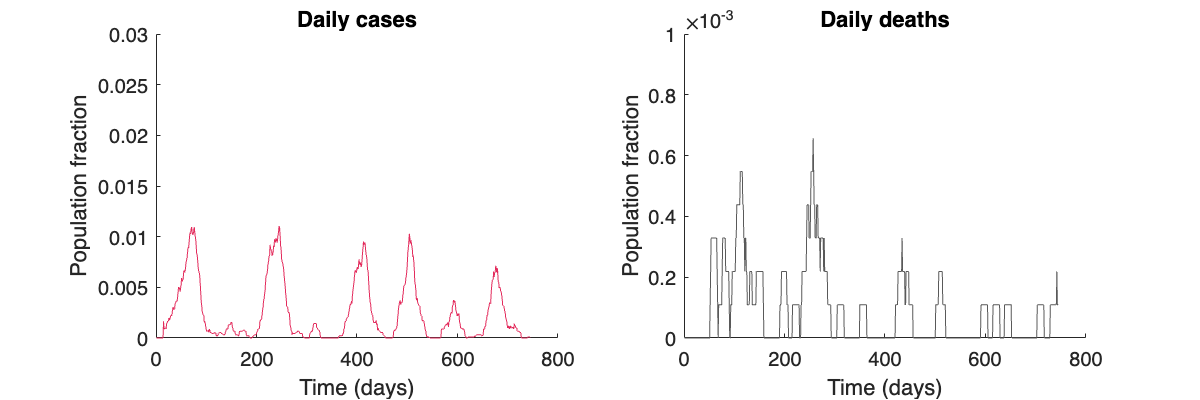

combinedScenario = ScenarioData('Policy_combination_data/grafica.csv', 'Policy_combination_data/city_info.csv', FsSEIRD, FsPlaces);
f = figure();
f.Position = [0 0 600 200];

subplot(1,2,1)
hold on 
combinedScenario.plotNewCases();
hold off
xlabel("Time (days)")
ylabel("Population fraction")
title("Daily cases")
ylim([0,0.03])
subplot(1,2,2)
hold on
combinedScenario.plotNewDeaths();
hold off
xlabel("Time (days)")
ylabel("Population fraction")
title("Daily deaths")
ylim([0,1*10^-3])

%matlab2tikz()

## Mobility time series

### Multi-policy scenario

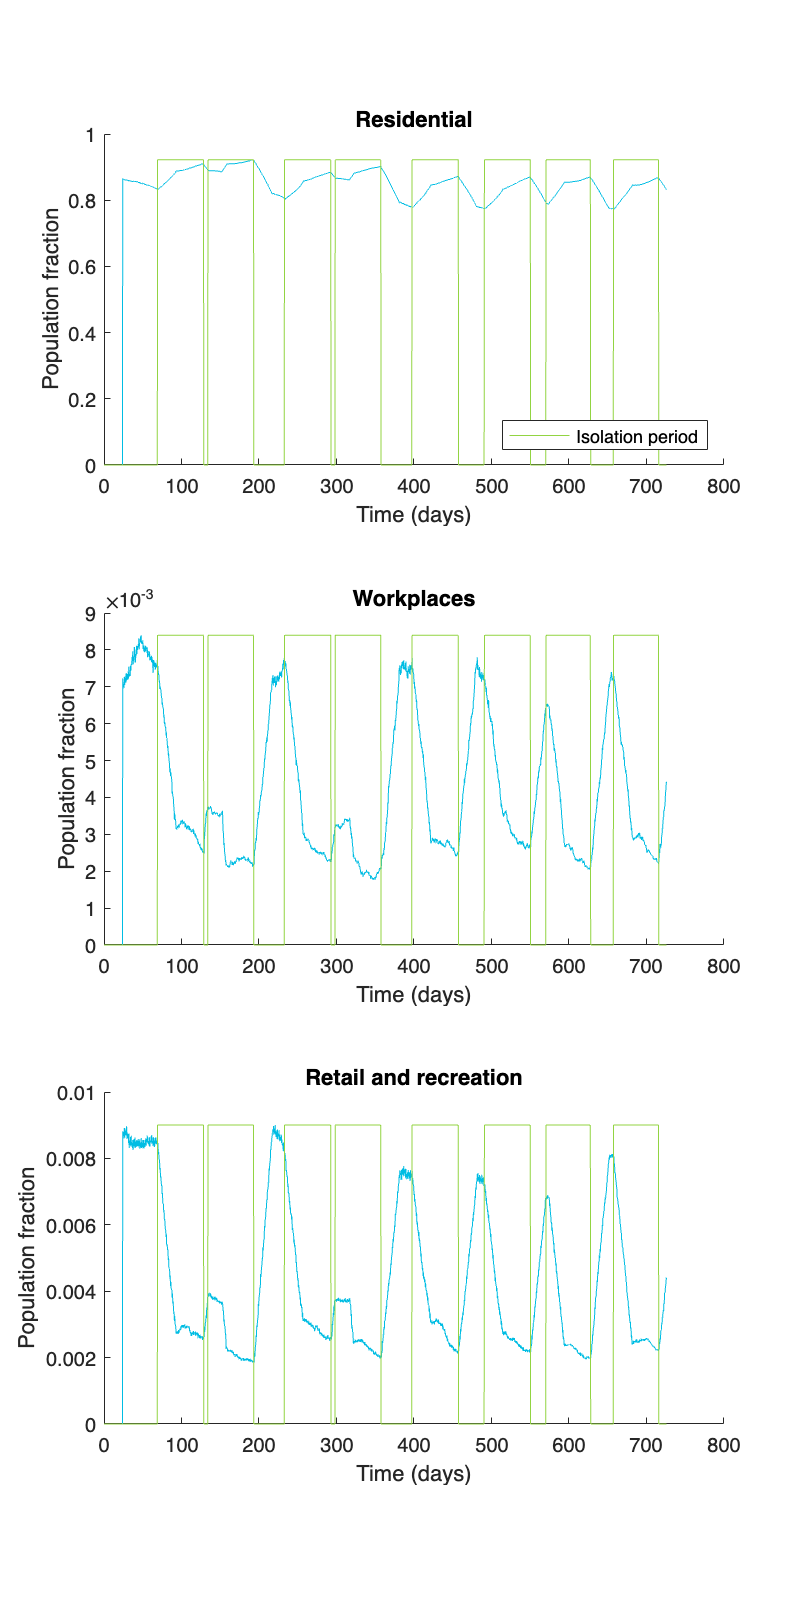

downSamplingRatio = 20;

f = figure();
f.Position = [0 0 400 800];
subplot(3,1,1)
hold on 
plot(downsample(combinedScenario.tArrayPlaces,downSamplingRatio), downsample(combinedScenario.residentialData,downSamplingRatio), 'Color', '#00bde3','HandleVisibility','off' )
plot(downsample(combinedScenario.tArrayPlaces,downSamplingRatio), downsample(combinedScenario.stoplightData,downSamplingRatio)*max(downsample(combinedScenario.residentialData,downSamplingRatio)),'Color', '#92d442', 'DisplayName', 'Isolation period')
hold off
title({'';"Residential"})
ylabel("Population fraction")
xlabel("Time (days)")
legend('Location','southeast')
subplot(3,1,2)
hold on 
plot(downsample(combinedScenario.tArrayPlaces,downSamplingRatio), downsample(combinedScenario.workplaceData,downSamplingRatio), 'Color', '#00bde3')
plot(downsample(combinedScenario.tArrayPlaces,downSamplingRatio), downsample(combinedScenario.stoplightData,downSamplingRatio)*max(downsample(combinedScenario.workplaceData,downSamplingRatio)),'Color', '#92d442')
hold off
title({'';"Workplaces"})
ylabel("Population fraction")
xlabel("Time (days)")
subplot(3,1,3)
hold on 
plot(downsample(combinedScenario.tArrayPlaces,downSamplingRatio), downsample(combinedScenario.recreationalData,downSamplingRatio), 'Color', '#00bde3')
plot(downsample(combinedScenario.tArrayPlaces,downSamplingRatio), downsample(combinedScenario.stoplightData,downSamplingRatio)*max(downsample(combinedScenario.recreationalData,downSamplingRatio)),'Color', '#92d442')
hold off
title({'';"Retail and recreation"})
ylabel("Population fraction")
xlabel("Time (days)")

%matlab2tikz()

#### Residences

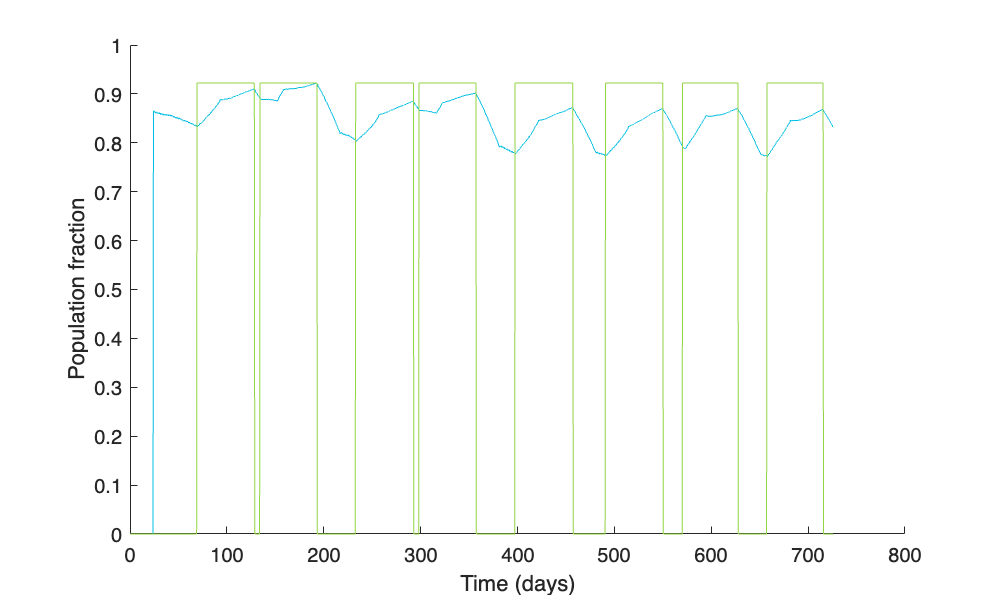

f = figure();
f.Position = [0 0 500 300];
hold on 
plot(downsample(combinedScenario.tArrayPlaces,downSamplingRatio), downsample(combinedScenario.residentialData,downSamplingRatio), 'Color', '#00bde3','HandleVisibility','off' )
plot(downsample(combinedScenario.tArrayPlaces,downSamplingRatio), downsample(combinedScenario.stoplightData,downSamplingRatio)*max(downsample(combinedScenario.residentialData,downSamplingRatio)),'Color', '#92d442', 'DisplayName', 'Isolation period')
hold off
%title({'';"Residential"})
ylabel("Population fraction")
xlabel("Time (days)")

%matlab2tikz()

#### Workplaces and retail and recreation

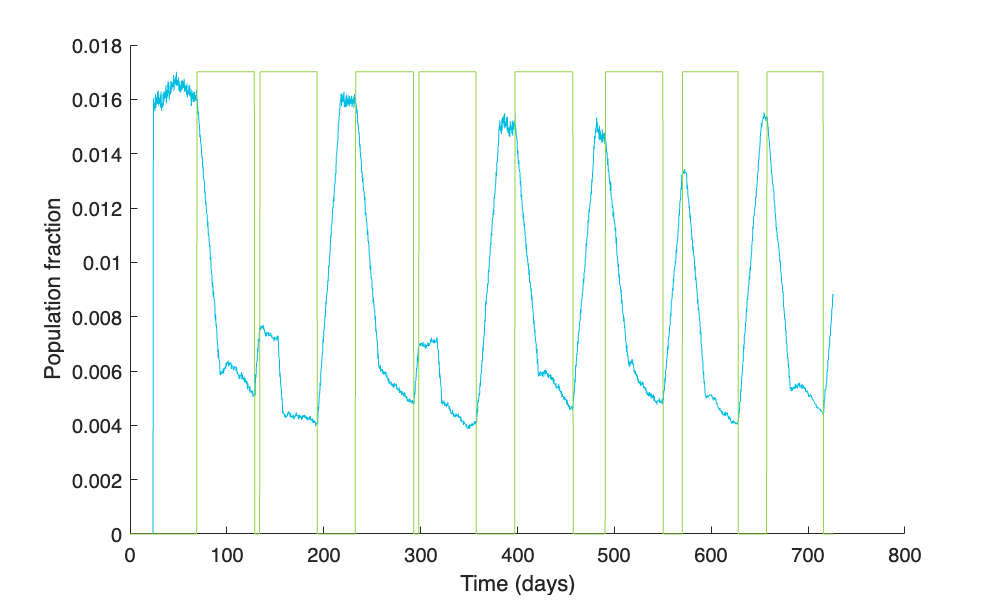

f = figure();
f.Position  = [0 0 500 300];
hold on 
plot(downsample(combinedScenario.tArrayPlaces,downSamplingRatio), downsample(combinedScenario.workplaceData,downSamplingRatio) + downsample(combinedScenario.recreationalData,downSamplingRatio), 'Color', '#00bde3')
plot(downsample(combinedScenario.tArrayPlaces,downSamplingRatio), downsample(combinedScenario.stoplightData,downSamplingRatio)*max(downsample(combinedScenario.workplaceData,downSamplingRatio) + downsample(combinedScenario.recreationalData,downSamplingRatio)),'Color', '#92d442')
hold off
%title({'';"Workplaces"})
ylabel("Population fraction")
xlabel("Time (days)")

%matlab2tikz()

### Lockdown scenario

#### Workplaces & retail and recreation

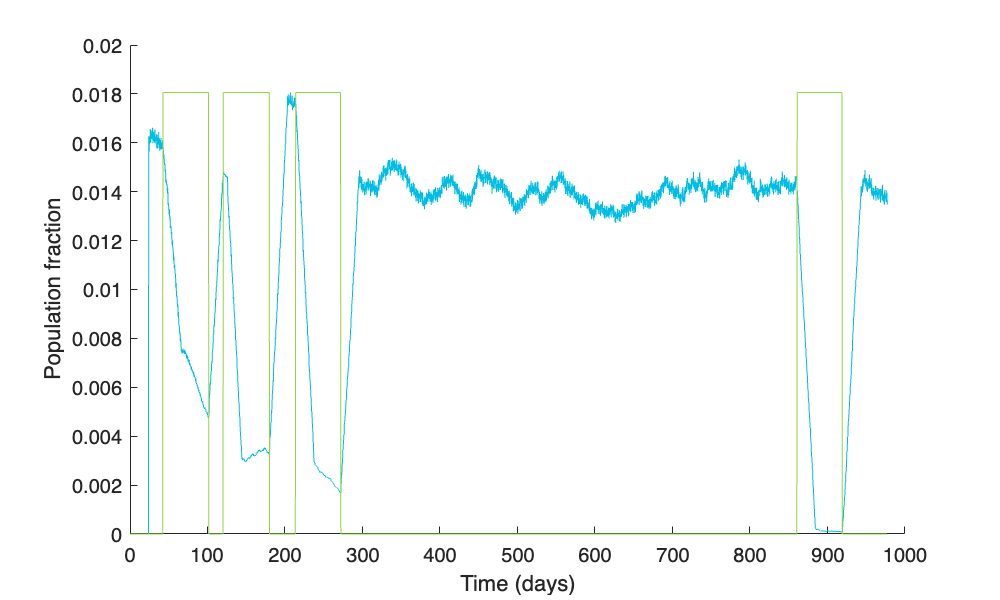

f = figure();
f.Position  = [0 0 500 300];
hold on 
plot(downsample(isolationScenario.tArrayPlaces,downSamplingRatio), downsample(isolationScenario.workplaceData,downSamplingRatio) + downsample(isolationScenario.recreationalData,downSamplingRatio), 'Color', '#00bde3')
plot(downsample(isolationScenario.tArrayPlaces,downSamplingRatio), downsample(isolationScenario.stoplightData,downSamplingRatio)*max(downsample(isolationScenario.workplaceData,downSamplingRatio) + downsample(isolationScenario.recreationalData,downSamplingRatio)),'Color', '#92d442')
hold off
%title({'';"Workplaces"})
ylabel("Population fraction")
xlabel("Time (days)")

#### Residences

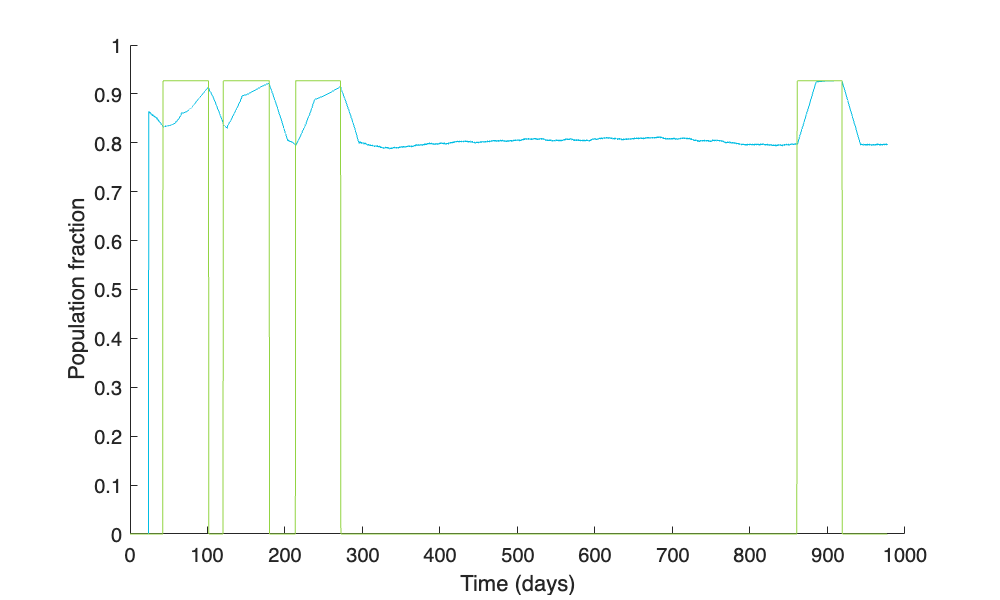

f = figure();
f.Position = [0 0 500 300];
hold on 
plot(downsample(isolationScenario.tArrayPlaces,downSamplingRatio), downsample(isolationScenario.residentialData,downSamplingRatio), 'Color', '#00bde3','HandleVisibility','off' )
plot(downsample(isolationScenario.tArrayPlaces,downSamplingRatio), downsample(isolationScenario.stoplightData,downSamplingRatio)*max(downsample(isolationScenario.residentialData,downSamplingRatio)),'Color', '#92d442', 'DisplayName', 'Isolation period')
hold off
%title({'';"Residential"})
ylabel("Population fraction")
xlabel("Time (days)")

### Vaccination

#### Workplaces + retail and recreation

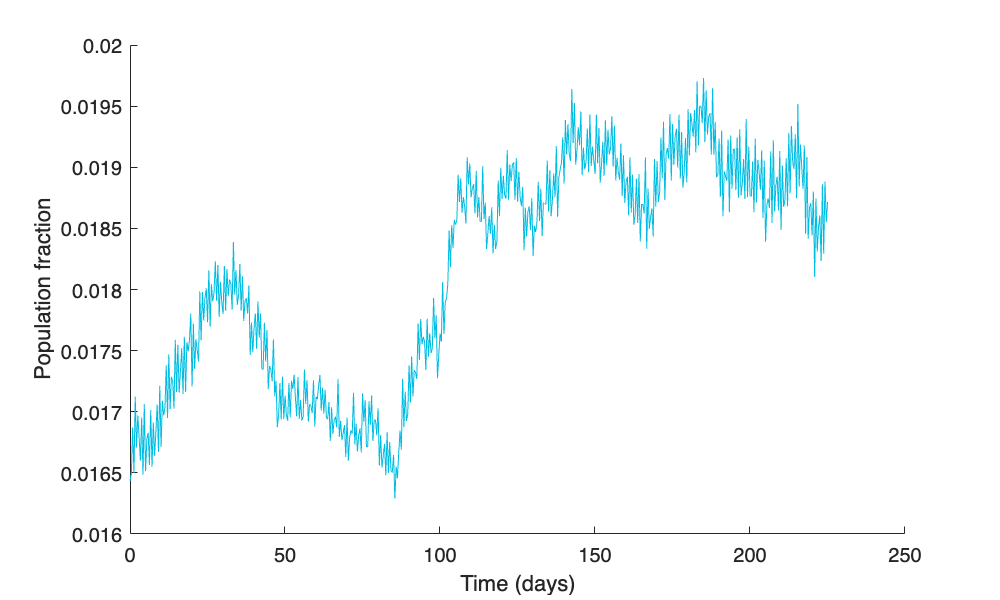


downSamplingRatio = 20;
downTArray = downsample(vaccinationScenario.tArrayPlaces,downSamplingRatio);
downWorkplaceArray = downsample(vaccinationScenario.workplaceData,downSamplingRatio) + downsample(vaccinationScenario.recreationalData, downSamplingRatio);

f = figure();
f.Position = [0 0 500 300];

pointStart = 60;
pointEnd = 600;

hold on 
plot(downTArray(1:pointEnd - pointStart+1),downWorkplaceArray(pointStart:pointEnd), 'Color', '#00bde3')
%plot(downsample(vaccinationScenario.tArrayPlaces,downSamplingRatio), downsample(vaccinationScenario.stoplightData,downSamplingRatio)*max(downsample(combinedScenario.workplaceData,downSamplingRatio)),'Color', '#92d442')
hold off
%title({'';"Workplaces + Retail & Recreation"})
ylabel("Population fraction")
xlabel("Time (days)")

#### Residences

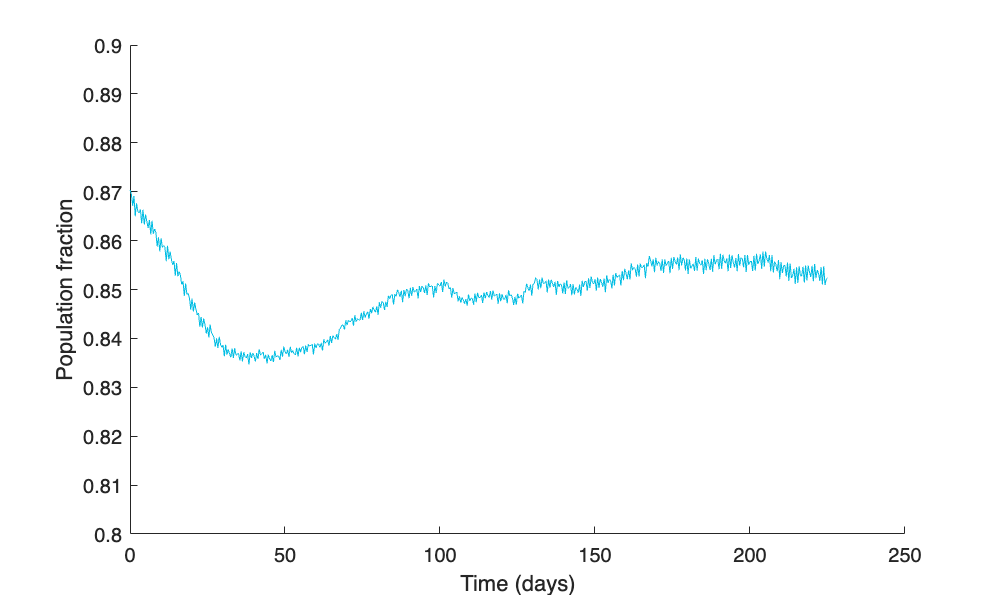

downSamplingRatio = 20;
downTArray = downsample(vaccinationScenario.tArrayPlaces,downSamplingRatio);
downHouseArray = downsample(vaccinationScenario.residentialData,downSamplingRatio);

f = figure();
f.Position = [0 0 500 300];

pointStart = 60;
pointEnd = 600;

hold on 
plot(downTArray(1:pointEnd-pointStart+1),downHouseArray(pointStart:pointEnd), 'Color', '#00bde3')
%plot(downsample(vaccinationScenario.tArrayPlaces,downSamplingRatio), downsample(vaccinationScenario.stoplightData,downSamplingRatio)*max(downsample(combinedScenario.workplaceData,downSamplingRatio)),'Color', '#92d442')
hold off
%title({'';"Residential"})
ylabel("Population fraction")
xlabel("Time (days)")
ylim([0.8,0.9])